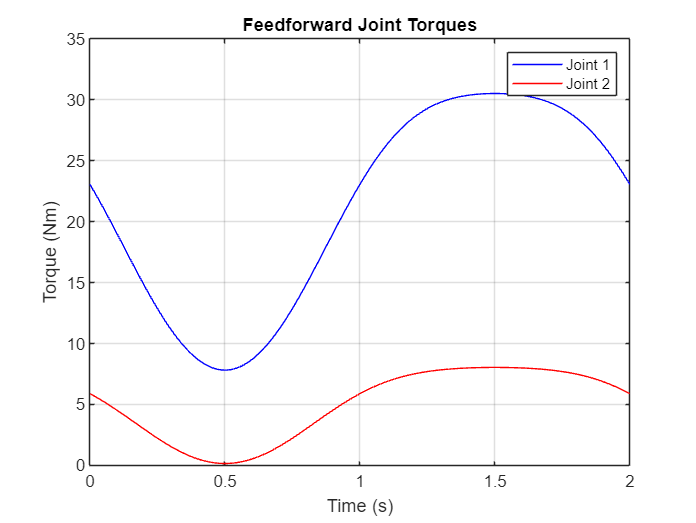

% Feedforward Control for 2-DOF Planar Manipulator
clear all; clc;

% Define manipulator parameters
n = 2; % Number of joints
L1 = 1.0; % Length of link 1 (m)
L2 = 0.8; % Length of link 2 (m)
m1 = 2.0; % Mass of link 1 (kg)
m2 = 1.5; % Mass of link 2 (kg)
g = [0; -9.81; 0]; % Gravity vector (m/s^2)

% Configuration matrices M_{i,i-1} (frames at centers of mass)
M{1} = [1, 0, 0, -0.5; 0, 1, 0, 0; 0, 0, 1, 0; 0, 0, 0, 1]; % M_{1,0}
M{2} = [1, 0, 0, -0.4; 0, 1, 0, 0; 0, 0, 1, 0; 0, 0, 0, 1]; % M_{2,1}
M{3} = [1, 0, 0, -0.4; 0, 1, 0, 0; 0, 0, 1, 0; 0, 0, 0, 1];

% Screw axes A_i (expressed in COM frames)
A{1} = [0; 0; 1; 0; 0.5; 0]; % Joint 1
A{2} = [0; 0; 1; 0; 0.4; 0]; % Joint 2

% Spatial inertia matrices G_i
I1 = [0, 0, 0; 0, 0, 0; 0, 0, (1/12)*m1*L1^2];
G{1} = [I1, zeros(3); zeros(3), m1*eye(3)];
I2 = [0, 0, 0; 0, 0, 0; 0, 0, (1/12)*m2*L2^2];
G{2} = [I2, zeros(3); zeros(3), m2*eye(3)];

% Animation screw axes
S_1 = [0; 0; 1; 0; 0; 0]; % Joint 1 at origin
S_2 = [0; 0; 1; 0; -1; 0]; % Joint 2

% Animation configuration matrices
M_0_1 = [1, 0, 0, 1; 0, 1, 0, 0; 0, 0, 1, 0; 0, 0, 0, 1]; % Base to joint 2
M_0_2 = [1, 0, 0, 1.8; 0, 1, 0, 0; 0, 0, 1, 0; 0, 0, 0, 1]; % Joint 2 to end-effector


% Simulation parameters
tf = 2.0; % Simulation time (s)
N = 500; % Number of integration steps
dt = tf / N;
t = linspace(0, tf, N+1);

% Desired trajectory (sinusoidal)
theta_d = [0.5 * sin(2 * pi * t / tf); 0.3 * sin(2 * pi * t / tf)];
theta_dot_d = [0.5 * (2 * pi / tf) * cos(2 * pi * t / tf); 0.3 * (2 * pi / tf) * cos(2 * pi * t / tf)];
theta_ddot_d = [-0.5 * (2 * pi / tf)^2 * sin(2 * pi * t / tf); -0.3 * (2 * pi / tf)^2 * sin(2 * pi * t / tf)];

% Initial conditions (match desired trajectory at t=0)
theta0 = theta_d(:,1); % [0; 0]
theta_dot0 = theta_dot_d(:,1); % [0.5 * 2 * pi / tf; 0.3 * 2 * pi / tf]

% Simulation storage
theta = zeros(n, N+1);
theta_dot = zeros(n, N+1);
F_tip = [0; 0; 0; 0; 0; 0]; % External wrench (N·m, N)

tau_array = zeros(n, N+1);

% Precompute torque profile using desired trajectory
for k = 1:N+1
    tau_array(:,k) = inverse_dynamics(theta_d(:,k), theta_dot_d(:,k), theta_ddot_d(:,k), F_tip, M, A, G, g);
end

for k = 1:N
    tau = tau_array(:,k);  % Use precomputed torque
    theta_ddot = compute_forward_dynamics(theta(:,k), theta_dot(:,k), tau, F_tip, M, A, G, g);

    theta(:,k+1) = theta(:,k) + theta_dot(:,k) * dt;
    theta_dot(:,k+1) = theta_dot(:,k) + theta_ddot * dt;
end


figure;
plot(t, tau_array(1,:), 'b-', t, tau_array(2,:), 'r-');
title('Feedforward Joint Torques');
xlabel('Time (s)');
ylabel('Torque (Nm)');
legend('Joint 1', 'Joint 2');
grid on;

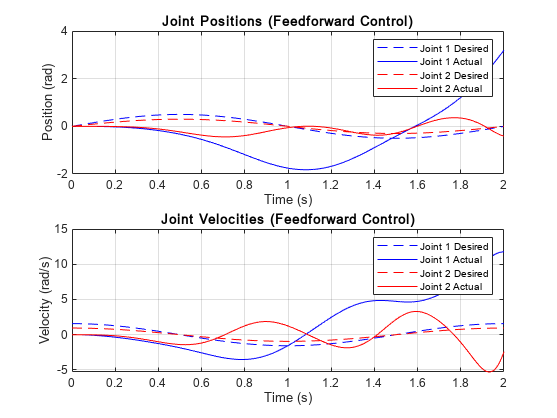


% Plot results
figure;
subplot(2,1,1);
plot(t, theta_d(1,:), 'b--', t, theta(1,:), 'b-', t, theta_d(2,:), 'r--', t, theta(2,:), 'r-');
title('Joint Positions (Feedforward Control)');
xlabel('Time (s)');
ylabel('Position (rad)');
legend('Joint 1 Desired', 'Joint 1 Actual', 'Joint 2 Desired', 'Joint 2 Actual');
grid on;

subplot(2,1,2);
plot(t, theta_dot_d(1,:), 'b--', t, theta_dot(1,:), 'b-', t, theta_dot_d(2,:), 'r--', t, theta_dot(2,:), 'r-');
title('Joint Velocities (Feedforward Control)');
xlabel('Time (s)');
ylabel('Velocity (rad/s)');
legend('Joint 1 Desired', 'Joint 1 Actual', 'Joint 2 Desired', 'Joint 2 Actual');
grid on;

% 
% % Animation
% figure;
% hold on;
% grid on;
% axis equal;
% xlim([-2, 2]);
% ylim([-2, 2]);
% xlabel('X (m)');
% ylabel('Y (m)');
% title('2-DOF Manipulator Motion (Feedforward Control)');
% 
% for k = 1:N+1
%     T0_1 = expm(skew(S_1) * theta(1,k));
%     T1 = T0_1 * M_0_1;
%     T1_2 = expm(skew(S_2) * theta(2,k));
%     T2 = T0_1 * T1_2 * M_0_2;
%     
%     p0 = [0; 0; 0];
%     p1 = T1(1:3,4);
%     p2 = T2(1:3,4);
%     
%     cla;
%     plot([p0(1), p1(1)], [p0(2), p1(2)], 'b-', 'LineWidth', 2);
%     plot([p1(1), p2(1)], [p1(2), p2(2)], 'r-', 'LineWidth', 2);
%     plot(p0(1), p0(2), 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k');
%     plot(p1(1), p1(2), 'ko', 'MarkerSize', 6, 'MarkerFaceColor', 'k');
%     plot(p2(1), p2(2), 'ko', 'MarkerSize', 6, 'MarkerFaceColor', 'k');
%     
%     drawnow;
%     pause(0.01);
% end

% Include dynamics functions (same as original)

function J = compute_jacobian(theta, M, A)
    % Compute geometric Jacobian for an n-DOF serial manipulator
    % Inputs:
    %   theta: n×1 vector of joint angles/displacements
    %   M: Cell array of 4×4 configuration matrices, M{i} from frame {i} to {i-1} when theta(i)=0
    %   A: Cell array of 6×1 screw axes, A{i} in frame {i}
    % Output:
    %   J: 6×n Jacobian matrix (body Jacobian)
    
    n = length(theta);
    J_s = zeros(6, n); % Spatial Jacobian
    
    % Step 1: Compute M_{0,i} for each i (when theta = 0)
    M_0_i = cell(n, 1); % Store M_{0,i}
    T = eye(4); % Transformation from base frame
    for i = 1:n
        T = T * inv(M{i}); % M_{0,i} = inv(M{1}) * inv(M{2}) * ... * inv(M{i})
        M_0_i{i} = T;
    end
    
    % Step 2: Transform screw axes A_i to S_i (in base frame)
    S = cell(n, 1);
    for i = 1:n
        Ad_M_0_i = adjoint(M_0_i{i});
        S{i} = Ad_M_0_i * A{i}; % S_i = Ad_{M_{0,i}} A_i
    end
    
    % Step 3: Compute Spatial Jacobian J_s
    T = eye(4); % Reset T for forward kinematics with theta
    for i = 1:n
        % The i-th column of J_s
        Ad_T = adjoint(T); % T is T_{0,i-1}
        J_s(:,i) = Ad_T * S{i};
        
        % Update transformation to next frame: T = T * expm(skew(A{i}) * theta(i)) * inv(M{i})
        % Note: We need to use the screw axis in the local frame for the exponential
        T = T * expm(skew(S{i}) * theta(i));
    end
    
    % Step 4: Convert Spatial Jacobian to Body Jacobian
    % T is now T_{0,n} (base to frame {n})
    Ad_T_inv = adjoint(inv(T)); % Ad_{T_{n,0}} = Ad_{T_{0,n}}^{-1}
    J = Ad_T_inv * J_s; % J_b = Ad_{T_{n,0}} J_s
end

% Include inverse_dynamics, forward_dynamics, skew, adjoint, ad_matrix functions
function tau = inverse_dynamics(theta, theta_dot, theta_ddot, F_tip, M, A, G, g)
    n = length(theta);
    nu = cell(n+1, 1);
    nu_dot = cell(n+1, 1);
    F = cell(n+1, 1);
    tau = zeros(n, 1);
    
    nu{1} = zeros(6,1);
    nu_dot{1} = [zeros(3,1); -g];
    F{n+1} = F_tip;
    
    for i = 1:n
        T_i_im1 = expm(-skew(A{i}) * theta(i)) * M{i};
        Ad_T_i_im1 = adjoint(T_i_im1);
        nu{i+1} = A{i} * theta_dot(i) + Ad_T_i_im1 * nu{i};
        ad_nu_i = ad_matrix(nu{i+1});
        nu_dot{i+1} = A{i} * theta_ddot(i) + Ad_T_i_im1 * nu_dot{i} + ad_nu_i * A{i} * theta_dot(i);
    end
    
    for i = n:-1:1
        if i == n
            T_ip1_i = M{n+1}; % For the last link, no transformation to a "next" frame
        else
            T_ip1_i = expm(-skew(A{i+1}) * theta(i+1)) * M{i+1};
        end
        Ad_T_ip1_i_T = adjoint(T_ip1_i)';
        ad_nu_i_T = ad_matrix(nu{i+1})';
        F{i} = Ad_T_ip1_i_T * F{i+1} + G{i} * nu_dot{i+1} - ad_nu_i_T * (G{i} * nu{i+1});
        tau(i) = F{i}' * A{i};
    end
end

function [theta, theta_dot] = forward_dynamics(theta0, theta_dot0, tau, F_tip, M, A, G, g, tf, N)
    n = length(theta0);
    dt = tf / N;
    theta = zeros(n, N+1);
    theta_dot = zeros(n, N+1);
    theta(:,1) = theta0;
    theta_dot(:,1) = theta_dot0;
    
    for k = 1:N
        t = (k-1) * dt;
        if isa(tau, 'function_handle')
            tau_k = tau(t);
        else
            tau_k = tau;
        end
        if isa(F_tip, 'function_handle')
            F_tip_k = F_tip(t);
        else
            F_tip_k = F_tip;
        end
        theta_ddot = compute_forward_dynamics(theta(:,k), theta_dot(:,k), tau_k, F_tip_k, M, A, G, g);
        theta(:,k+1) = theta(:,k) + theta_dot(:,k) * dt;
        theta_dot(:,k+1) = theta_dot(:,k) + theta_ddot * dt;
    end
end

function theta_ddot = compute_forward_dynamics(theta, theta_dot, tau, F_tip, M, A, G, g)
    n = length(theta);
    h = inverse_dynamics(theta, theta_dot, zeros(n,1), zeros(6,1), M, A, G, g);
    M_theta = zeros(n, n);
    for i = 1:n
        theta_ddot_i = zeros(n,1);
        theta_ddot_i(i) = 1;
        M_theta(:,i) = inverse_dynamics(theta, zeros(n,1), theta_ddot_i, zeros(6,1), M, A, G, zeros(3,1));
    end
    J = compute_jacobian(theta, M, A);
    theta_ddot = (M_theta) \ (tau - h - J' * F_tip);
end

function S = skew(v)
    if length(v) == 3
        S = [0, -v(3), v(2); v(3), 0, -v(1); -v(2), v(1), 0];
    elseif length(v) == 6
        omega = v(1:3);
        v_linear = v(4:6);
        omega_skew = [0, -omega(3), omega(2); omega(3), 0, -omega(1); -omega(2), omega(1), 0];
        S = [omega_skew, v_linear; 0, 0, 0, 0];
    else
        error('Input vector must be 3x1 or 6x1');
    end
end

function Ad = adjoint(T)
    R = T(1:3, 1:3);
    p = T(1:3, 4);
    Ad = [R, zeros(3); skew(p) * R, R];
end

function ad = ad_matrix(V)
    omega = V(1:3);
    v = V(4:6);
    ad = [skew(omega), zeros(3); skew(v), skew(omega)];
end
